clear all;
close all;
%start time is July 02 2020 00:00:00
startTime = 20200702000000;
%end time is July 09 2020 18:00:00
endTime = 20200709180000;
%stn 100
stnID = 100;
gliderTable = readtable('metbuoy_19-04.csv');

cdipid = stnID; 
%convert startTime for cdip
    startTimestr = int2str(startTime);
    y_start = str2num(startTimestr(:,1:4));
    m_start = str2num(startTimestr(:,5:6));
    d_start = str2num(startTimestr(:,7:8));
    h_start = str2num(startTimestr(:,9:10));
    min_start = str2num(startTimestr(:,11:12));
    s_start = str2num(startTimestr(:,13:14));
    %convert endTime
    endTimestr = int2str(endTime);
    y_end = str2num(endTimestr(:,1:4));
    m_end = str2num(endTimestr(:,5:6));
    d_end = str2num(endTimestr(:,7:8));
    h_end = str2num(endTimestr(:,9:10));
    min_end = str2num(endTimestr(:,11:12));
    s_end = str2num(endTimestr(:,13:14));

tlims = [datenum(y_start,m_start,d_start,h_start,min_start,s_start) datenum(y_end, m_end,d_end,h_end,min_end,s_end)]; 

% spectral data etc. ------------------------------------------------------
clear cdip;
tres = 1;

varnm = 'Time';
[cdip.time] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Hs';
[cdip.hs] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Tp';
[cdip.tp] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'EnergyDensity';
[cdip.sf, cdip.f] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'MeanDirection';
[cdip.md] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



%get waveglider time and wind vectors for appropriate times
[wgt,wgWind,wgMeanDir,~] = gliderTime(gliderTable, startTime, endTime);

%remove waveglider times that have no corresonding values in energy times
t_wind_new = NaN(length(cdip.time),1);
wind_wave_indices = NaN(length(cdip.time),1);
diff = 1000;
index = 1;
    for i = 1:length(cdip.time)
      for j = 1:length(wgt)
        if abs(cdip.time(i)-wgt(j)) < diff
            diff = abs(cdip.time(i)-wgt(j));
            index = j;
        end
      end
      t_wind_new(i) = wgt(index);
      wind_wave_indices(i) = index;
      index = 1;
      diff = 1000;
    end    
%new wind speeds
wgWind = wgWind(wind_wave_indices);
%new mean direction
wgMeanDir = wgMeanDir(wind_wave_indices);
%new wind times
wgt = wgt(wind_wave_indices);

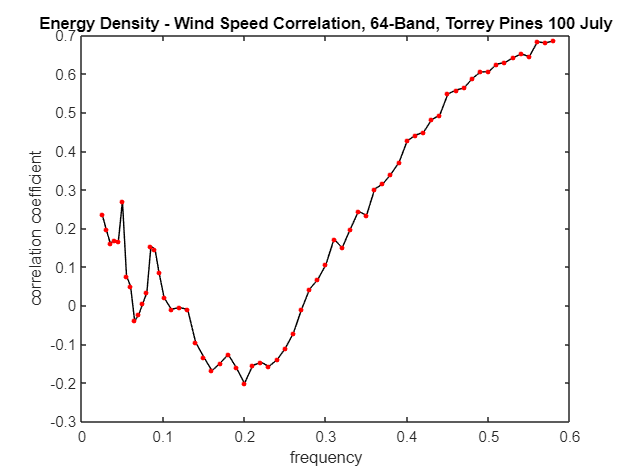

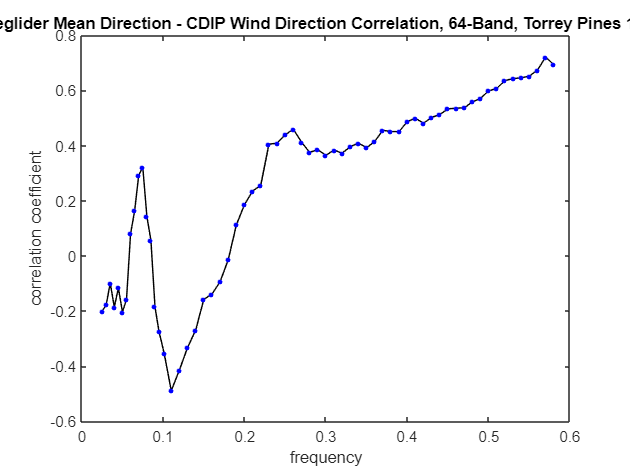

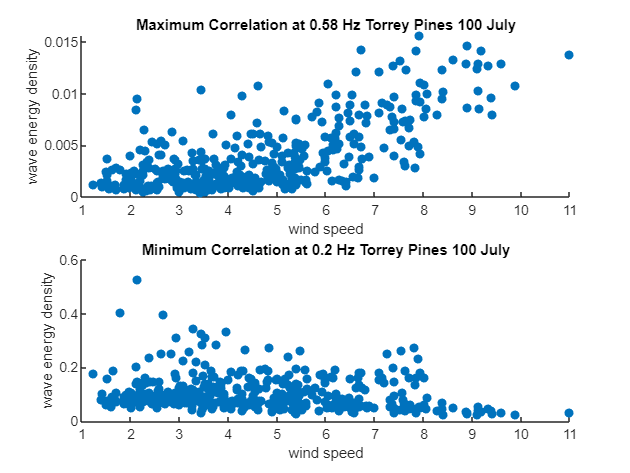

corr =     0.2365    0.1972    0.1616    0.1680    0.1658    0.2705    0.0762    0.0497   -0.0403   -0.0243    0.0052    0.0332    0.1534    0.1460    0.0845    0.0202   -0.0099   -0.0055   -0.0099   -0.0955   -0.1340   -0.1690   -0.1498   -0.1270   -0.1615   -0.2020   -0.1560   -0.1470   -0.1578   -0.1410   -0.1115   -0.0722   -0.0110    0.0423    0.0670    0.1055    0.1719    0.1492    0.1976    0.2437    0.2337    0.3017    0.3152    0.3401    0.3712    0.4267    0.4410    0.4487    0.4813    0.4934


dircorr =    -0.2010   -0.1784   -0.0988   -0.1863   -0.1164   -0.2040   -0.1581    0.0798    0.1635    0.2922    0.3215    0.1431    0.0566   -0.1856   -0.2763   -0.3532   -0.4894   -0.4144   -0.3329   -0.2696   -0.1578   -0.1388   -0.0940   -0.0143    0.1120    0.1861    0.2349    0.2559    0.4049    0.4088    0.4393    0.4590    0.4129    0.3753    0.3850    0.3651    0.3832    0.3727    0.3956    0.4088    0.3920    0.4147    0.4556    0.4505    0.4509    0.4866    0.4990    0.4811    0.5019    0.5127


[corr, dircorr] = windWaveCorr64(' Torrey Pines 100 July', wgWind, wgMeanDir, cdip)

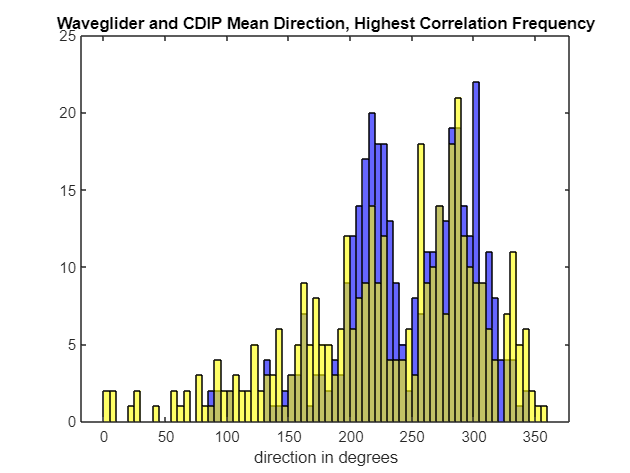

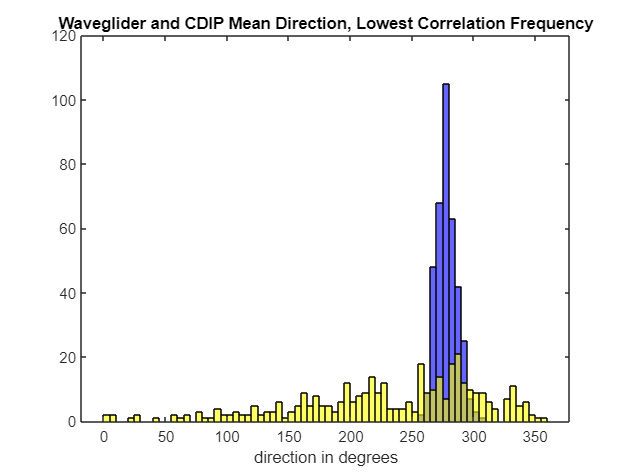

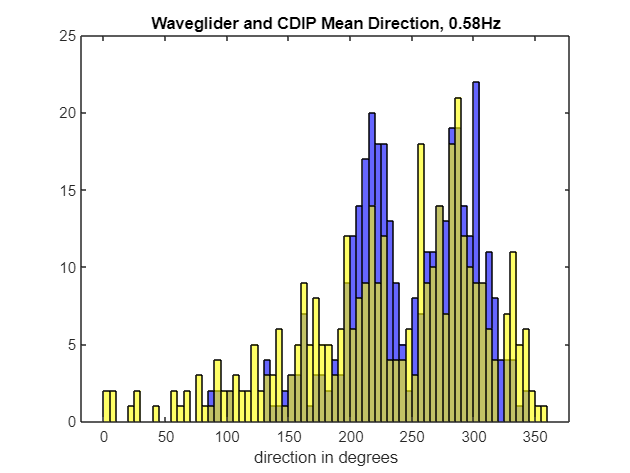

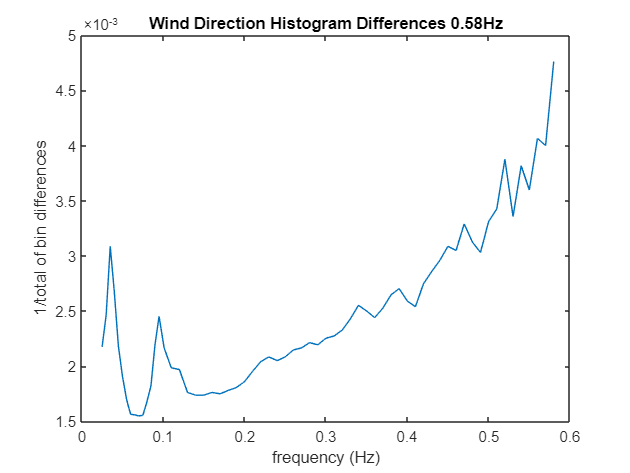

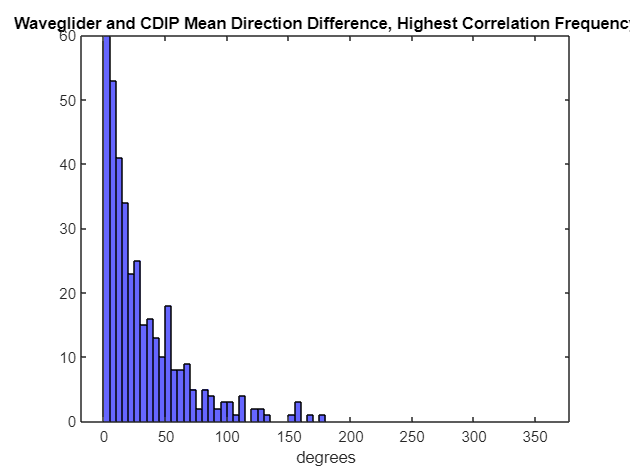

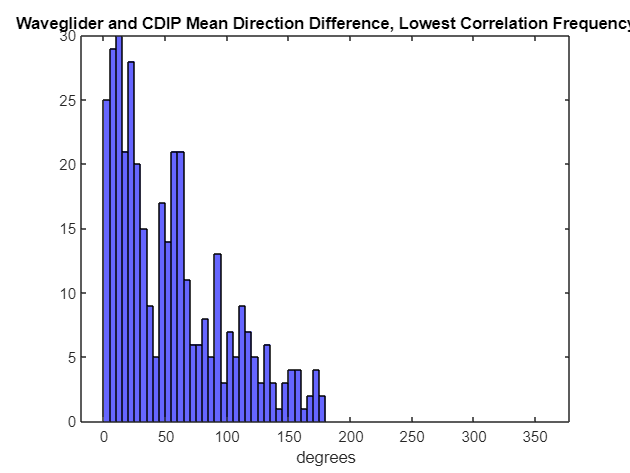

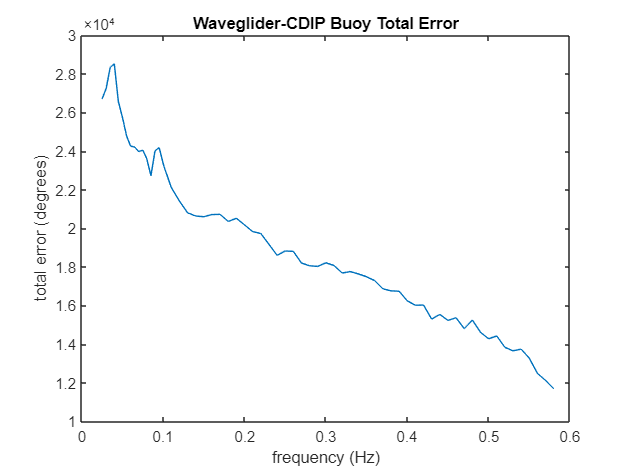

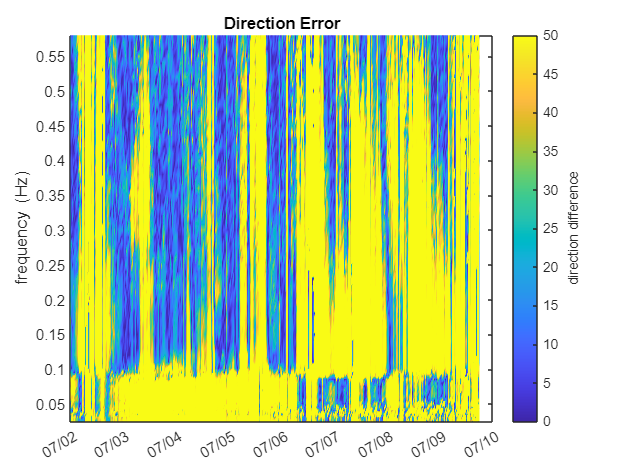

hist =     0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1013    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400
    0.0022    0.0025    0.0031    0.0027    0.0022    0.0019    0.0017    0.0016    0.0016    0.0015    0.0016    0.0017    0.0018    0.0022    0.0025    0.0022    0.0020    0.0020    0.0018    0.0017    0.0017    0.0018    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0020    0.0021    0.0021    0.0022    0.0022    0.0022    0.0023    0.0023    0.0023    0.0024    0.0026    0.0025    0.0024    0.0025    0.0026    0.0027    0.0026    0.0025    0.0027    0.0029  

%direction histograms
hist = dir_histogram(cdip, wgMeanDir, corr)

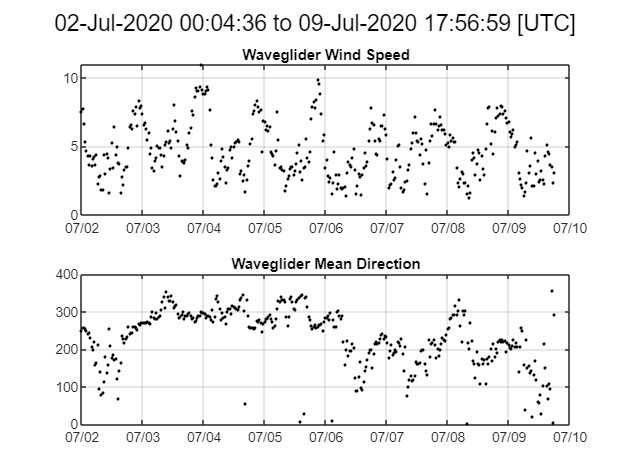

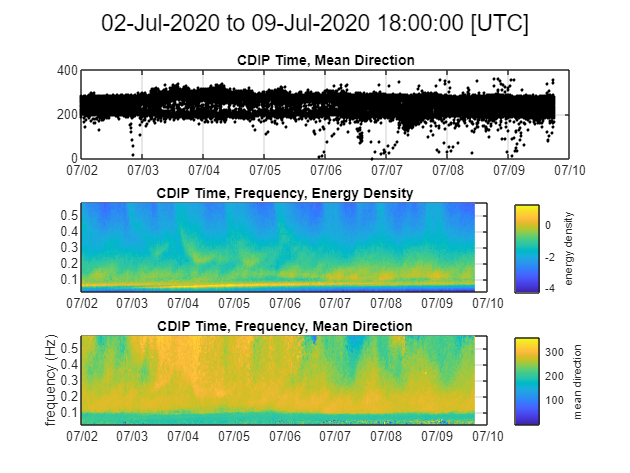

%pcolor plot
pcolor_plot(wgt, wgWind, wgMeanDir, cdip)

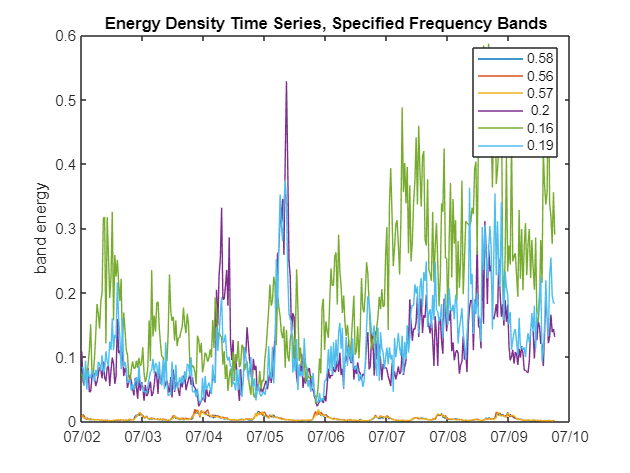

%energy density time series for selected frequency bands
freqplot(cdip, corr)